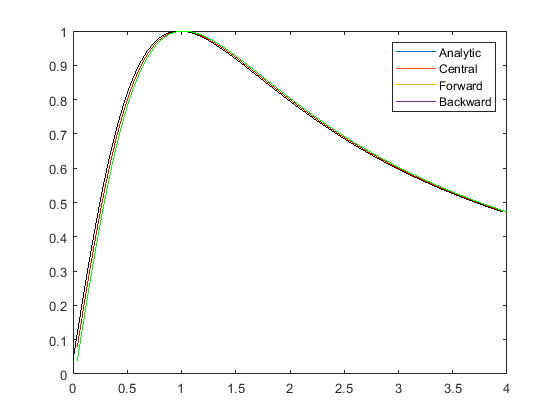


Fun=@(x) log(1+x.^2);
dFun=@(x) 2*x/(1+x.^2);
x=linspace(0,4,101);
F=Fun(x);
h=x(2)-x(1);
xCentral=x(2:end-1);
dFCenteral=(F(3:end)-F(1:end-2))/(2*h);
xForward=x(1:end-1);
dFForward=(F(2:end)-F(1:end-1))/h;
xBackward=x(2:end);
dFBackward=(F(2:end)-F(1:end-1))/h;
plot(x,dFun(x));
hold on
plot(xCentral,dFCenteral,'r')
plot(xForward,dFForward,'k');
plot(xBackward,dFBackward,'g');
legend('Analytic','Central','Forward','Backward')